# Lab 6: Blood Pressure

**By Ari Porad**

**Introduction to Sensors, Instrumentation, and Measurement**

**April 22nd 2021**

## Abstract

A test subject's heartbeat was measured using a blood pressure cuff outfitted with a pressure sensor. The output of the pressure sensor was fed through two high-pass filters, an amplifier, and a low-pass filter to produce a clean and easily-mesaureable signal. This method showed great promise as a means of measuring heart rate, although further investigation to evaluate its versatility and accuracy is required.

## Methodology

We used an MPX5050DP pressure sensor connected to a blood pressure cuff to measure the test subject's blood pressure. The output from this pressure sensor was fed into an two-high pass filters (each with a characteristic frequency of 0.8Hz), an op-amp amplifier (with a gain of 31), and a low-pass filter (with a characteristic frequency of of 5.3Hz) to sanitize the data. The high-pass filters aimed to filter out the slowly decaying pressure of the cuff (during measurement, the cuff was depresurized at a constant rate to enable determining the test subject's blood pressure), while the low-pass filter aimed to sanitize any electrical noise while keeping the heart beat (on the order of ~1Hz) intact. The op-amp was used to increase the voltage to easily measurable levels. The characteristic frequencies and gain levels were initially chosen based on normal human heart rates, then refined with experimentation. We used 2.5V as the reference voltage for our high-pass filters and amplifier to enable measuring voltages below the mean voltage, which is impossible if 0V is used as the reference voltage (because a negative voltage is impossible).

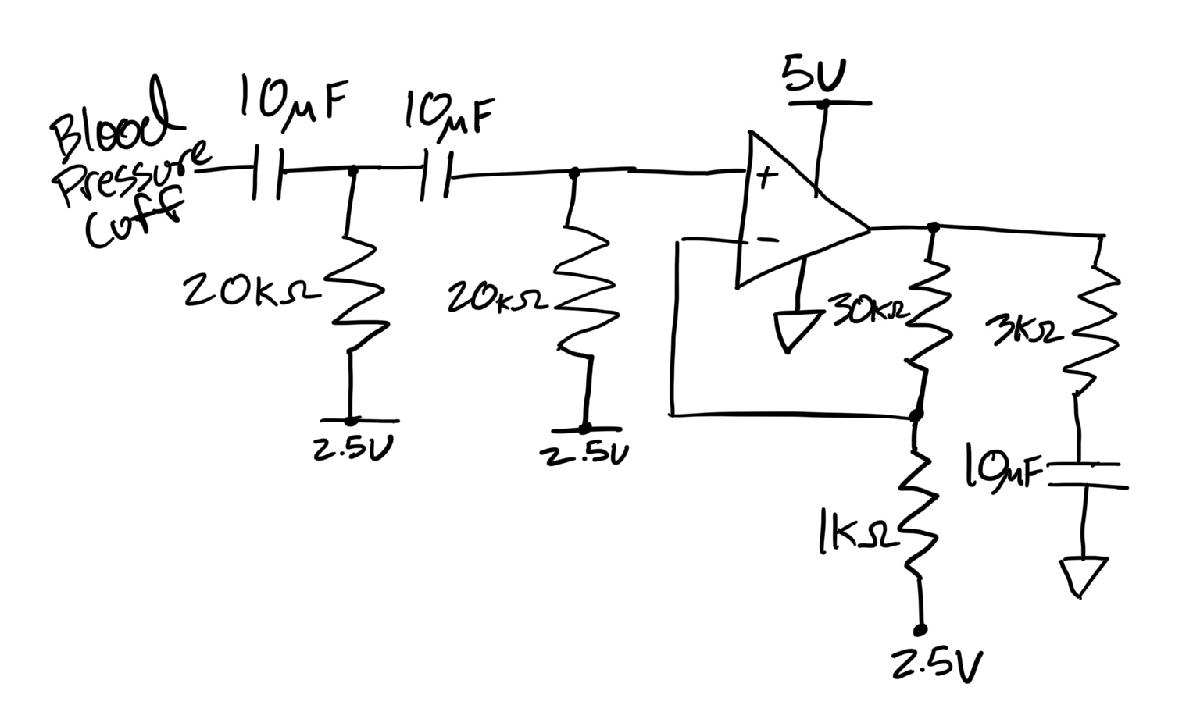

**Figure 1.** A schematic of the circuit we used to measure the test subject's blood pressure. We used two high-pass filters, an op-amp amplifier, and a low-pass filter to sanitize the incoming data for easy processing.

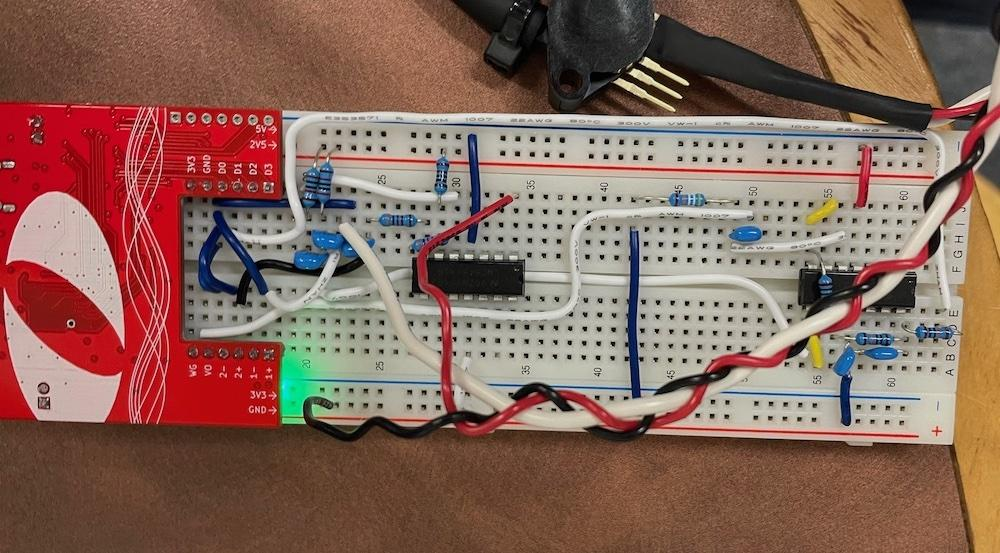

**Figure 2.** The breadboard with our fully-constructed circuit, as described in the above schematic.The long cable running to the pressure sensor in the blood pressure cuff can be seen.

## Results

We found that our system was highly effective at filtering the pressure sensor's output, to the point that it could be used to measure the test subject's heart rate.

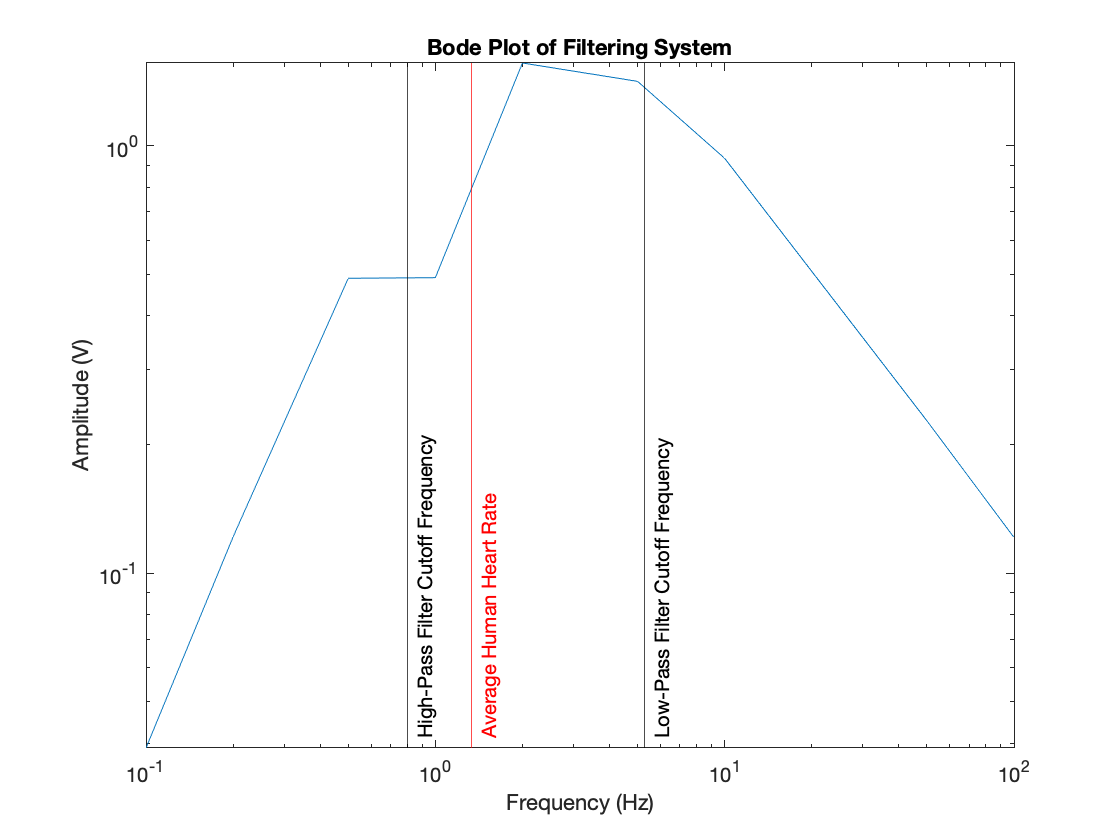

clear all;
f = figure(3); clf;
load("bode.mat");
loglog(freq, V_out);
xlabel("Frequency (Hz)");
ylabel("Amplitude (V)");
title("Bode Plot of Filtering System")
xline(0.8, "k", "High-Pass Filter Cutoff Frequency", "LabelVerticalAlignment", "bottom");
xline(5.3, "k", "Low-Pass Filter Cutoff Frequency", "LabelVerticalAlignment", "bottom");
xline(80 / 60, "r", "Average Human Heart Rate", "LabelVerticalAlignment", "bottom"); % https://www.mayoclinic.org/healthy-lifestyle/fitness/expert-answers/heart-rate/faq-20057979

clear all;

**Figure 3.** A Bode plot of the filtering system, including the cutoff frequencies of the high- and low- pass filters (0.8Hz and 5.3Hz, respectively) and an average human heart rate (80bpm / 1.33Hz). Demonstrates that the filtering system is highly effective at filtering out frequencies out of normal human heartbeat range.

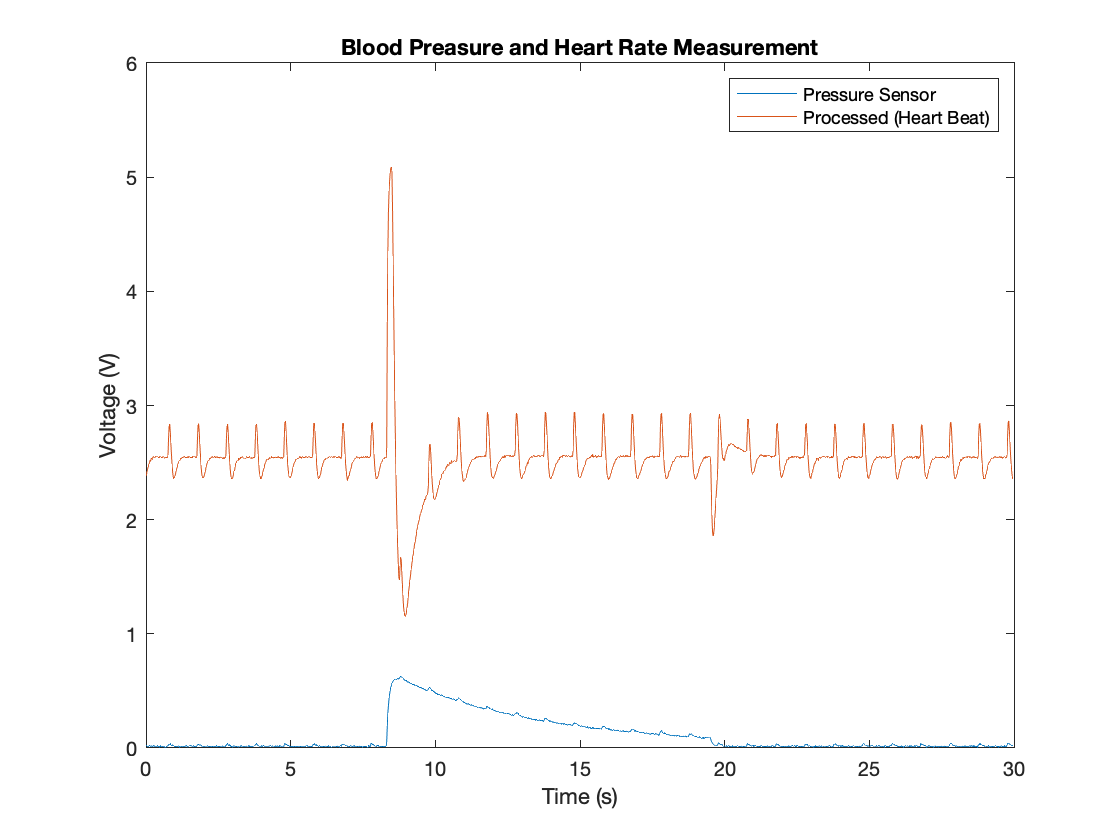

figure(4); clf;
load("data.mat");
plot(T, V_in); hold on;
plot(T, V_out); hold off;
ylabel("Voltage (V)");
xlabel("Time (s)");
legend("Pressure Sensor", "Processed (Heart Beat)");
title("Blood Preasure and Heart Rate Measurement");

clear all;

**Figure 3.** Voltages of the pressure sensor and filtered output over time. Test subject's heartbeat can be clearly seen in the filtered output, while the decay of the pressure cuff has been removed entirely. Filtered output has also been centered around 2.5V, allowing for a wider range of measurement.

## Finishing Remarks

In this experiment, we demonstrated the viability of using a blood pressure cuff and pressure sensor, along with various filtering and amplyfing techniques, to accurately measure a human's heartbeat. While that's promising, more research should be done to more fully assess the viability of this technique in more varried circumstances. Additionally, further investigation into additional information that could be inferred from this data would be valuable.

This experiment only collected data on one test subject, a healthy 19 year old male. Further testing against a wider range of candidates would be valuable for proving the system's versatility. Additionally, comparing the data to a known-good measuring system would enable us to judge the system's accuracy.